# L05B_examples

## Example 1 (no z-p canc)

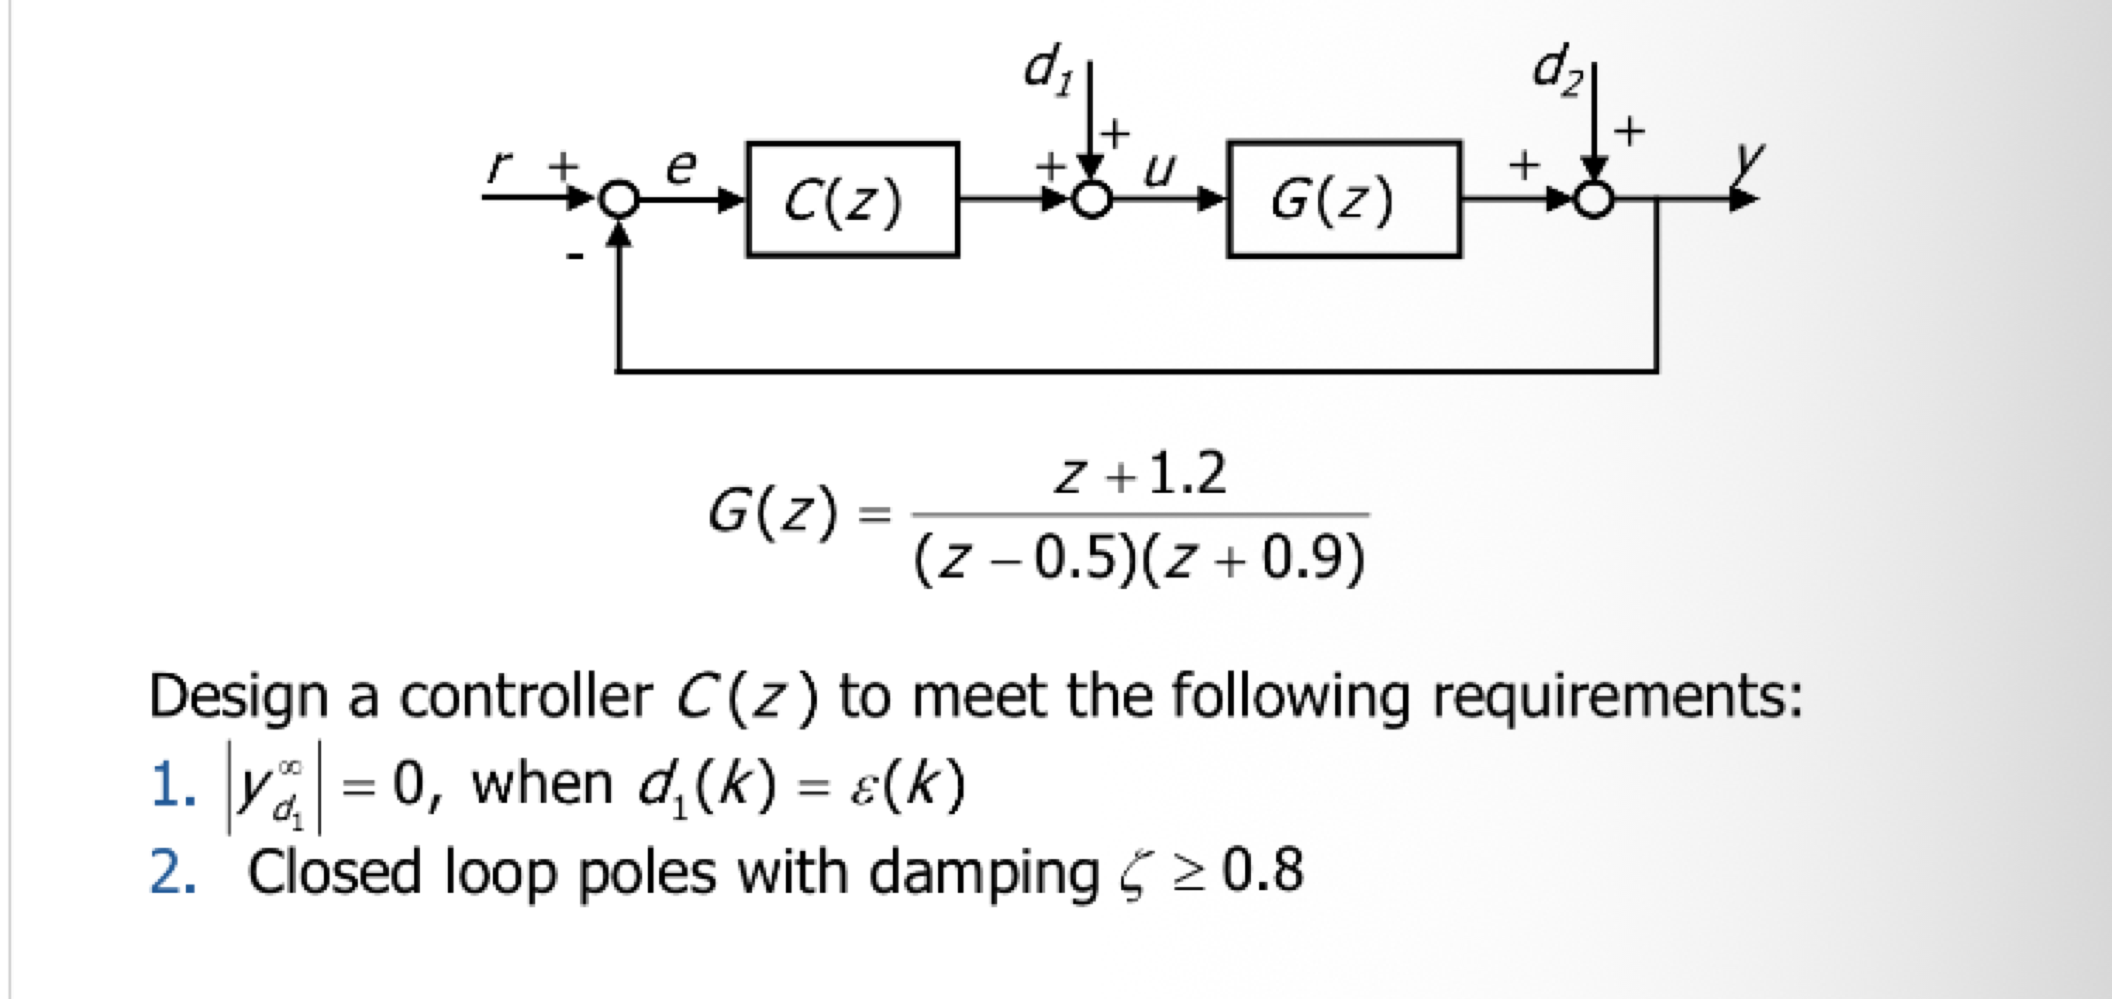

close all
clear
clc

z = tf('z',1);
G = (z+1.2)/((z-0.5)*(z+0.9));

In order to satisfy ss requirement (d1_inf = 0) we need, since d1 is a step, l2 = 1

The structure of the controller is:

C(z) = S(z) / ((z-1)R'(z))

l1 = 0; % power of (z-1) term in G
l2 = 1; % power of (z-1) term in C
l = l1+l2;

A1 = conv([1 -0.5], [1 0.9]);
B = [1 1.2];
deg_A = 2; % G has 2 poles
deg_A1 = 2; % no roots in 1 in G

deg_S = l + deg_A1 - 1

deg_S = 2

deg_R1 = l1 + deg_A1 - 1

deg_R1 = 1

deg_Am = l1 + deg_A1 + l2 + deg_R1

deg_Am = 4

So, I obtain these forms for C and Am

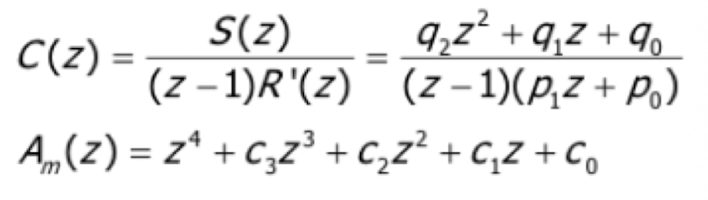

Now I have to choose the roots for Am, pay attention to the damping constraint

For example, I choose 0.2 +- j0.2 and 0.1 +- j0.1

To compute Am coeff I use matlab function poly

r = [0.2+0.2*1i, 0.2-0.2*1i, 0.1-0.1*1i, 0.1+0.1*1i]; % roots vector
Am = poly(r)'; % Am coeff

Now I have to solve diophantine equation

% before I define Adioph and Bdioph
Adioph = conv([1 -1], A1);
Bdioph = B;

[R1, S1] = diop_solver(Adioph,Bdioph,Am,deg_R1);
% NB Adioph Bdioph & Am can be both row or column

Then, I can build the controller

R = conv([1 -1], R1);
S = S1;
C = zpk(tf(S(:)',R(:)', 1));
% NB in tf S and R must be row

And, at the end, check if poles of closed loop tf are exacly the chosen ones

W = minreal(zpk(feedback(C*G,1)), 1e-2);
p_W = pole(W)

p_W =    0.2000 + 0.2000i
   0.2000 - 0.2000i
   0.1000 + 0.1000i
   0.1000 - 0.1000i


## Example 2 (z-p canc)

close all
clear
clc

z = tf('z',1);
G = (z+1.2)/((z-0.5)*(z+0.9)); % B(z)/A(z)

Before studying the ss requirements, it's important to represent G in zpk form and understand what roots can be cancelled

G = zpk(G) % B+(z)*B-(z) / (A+(z)*A-(z))


G =
 
      (z+1.2)
  ---------------
  (z+0.9) (z-0.5)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


I can clearly see that the only root that I can cancel is the pole (z-0.5)

So I can define the quantities A+,A-, B+,B- as:

A_plus = [1 -0.5];
A_minus = [1 0.9];
B_plus = 1;
B_minus = [1 1.2];

Now we can focus on requirements analysis:

In order to satisfy ss requirement (d1_inf = 0) we need, since d1 is a step, l2 = 1

The structure of the controller is:

C(z) = **A+(z)***S(z) / ((z-1)R'(z)***B+(z)**)

l1 = 0; % power of (z-1) term in G
l2 = 1; % power of (z-1) term in C
l = l1+l2;

deg_A = 2; % G has 2 poles
deg_A1 = 2; % no roots in 1 in G
deg_Aplus = 1;
deg_Aminus = 1;
deg_Bplus = 0;
deg_Bminus = 1;

% by def
deg_S1 = l + deg_Aminus - 1

deg_S1 = 1

deg_R2 = deg_A1 - deg_Bplus + l1 - 1

deg_R2 = 1

deg_Am = l + deg_Aminus + deg_A1 - deg_Bplus + l1 - 1 

deg_Am = 3

NOTE: in the previous example we got deg_Am = 4 and now deg_Am = 3, so **now we got a simpler tf**

So I obtain these quantities:

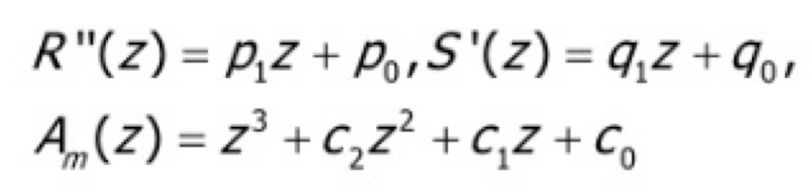

Now I have to choose the roots for Am, pay attention to the damping constraint

For example, I choose 0.2 +- j0.2 and 0.2

To compute Am coeff I use matlab function poly

r = [0.2+0.2*1i, 0.2-0.2*1i, 0.2]; % roots vector
Am = poly(r)'; % Am coeff

Now I have to solve diophantine equation

% before I define Adioph and Bdioph
A_dioph = conv([1 -1], A_minus);
B_dioph = B_minus;

[R2, S1] = diop_solver(A_dioph,B_dioph,Am,deg_R2);
% NB Adioph Bdioph & Am can be both row or column

Then, I can build the controller

R = conv([1 -1], R2); % I can omit B+ term since B+ = 1
S = conv(A_plus,S1);
C = zpk(tf(S(:)',R(:)', 1));
% NB in tf S and R must be row

And, at the end, check if poles of closed loop tf are exacly the chosen ones

W = minreal(zpk(feedback(C*G,1)), 1e-2);
p_W = pole(W)

p_W =    0.2000 + 0.0000i
   0.2000 + 0.2000i
   0.2000 - 0.2000i


## Example 3 (z-p canc with extra eq)

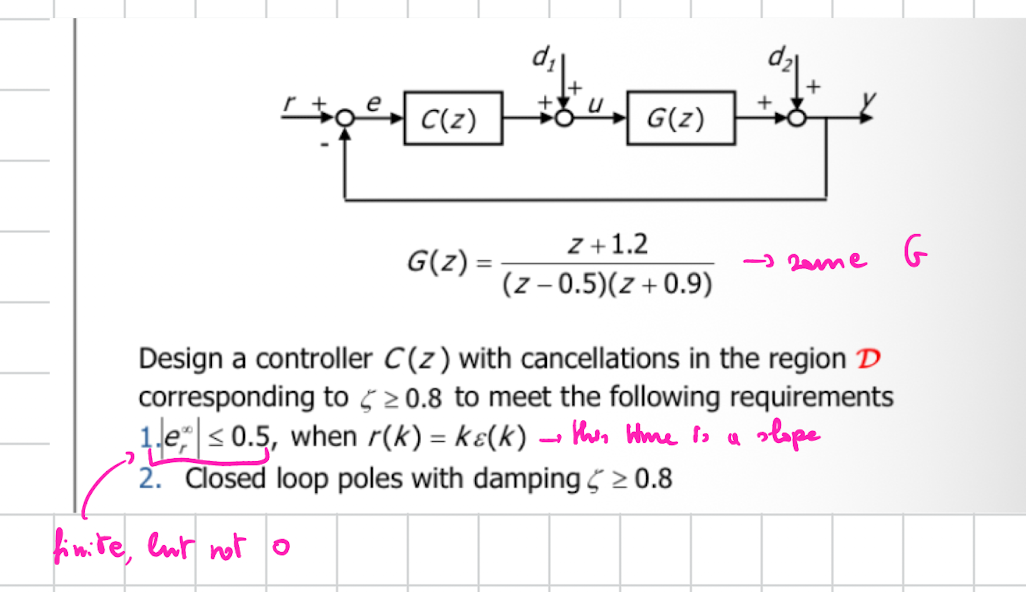

close all
clear
clc

z = tf('z',1);
G = (z+1.2)/((z-0.5)*(z+0.9)); % B(z)/A(z)

Before studying the ss requirements, it's important to represent G in zpk form and understand what roots can be cancelled

G = zpk(G) % B+(z)*B-(z) / (A+(z)*A-(z))


G =
 
      (z+1.2)
  ---------------
  (z+0.9) (z-0.5)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


I can clearly see that the only root that I can cancel is the pole (z-0.5)

So I can define the quantities A+,A-, B+,B- as:

A_plus = [1 -0.5];
A_minus = [1 0.9];
B_plus = 1;
B_minus = [1 1.2];

Now we can focus on requirements analysis:

The ss requirement is different wrt to past examples, in particular we have a ramp signal and a finite value for e_inf

According to the table:

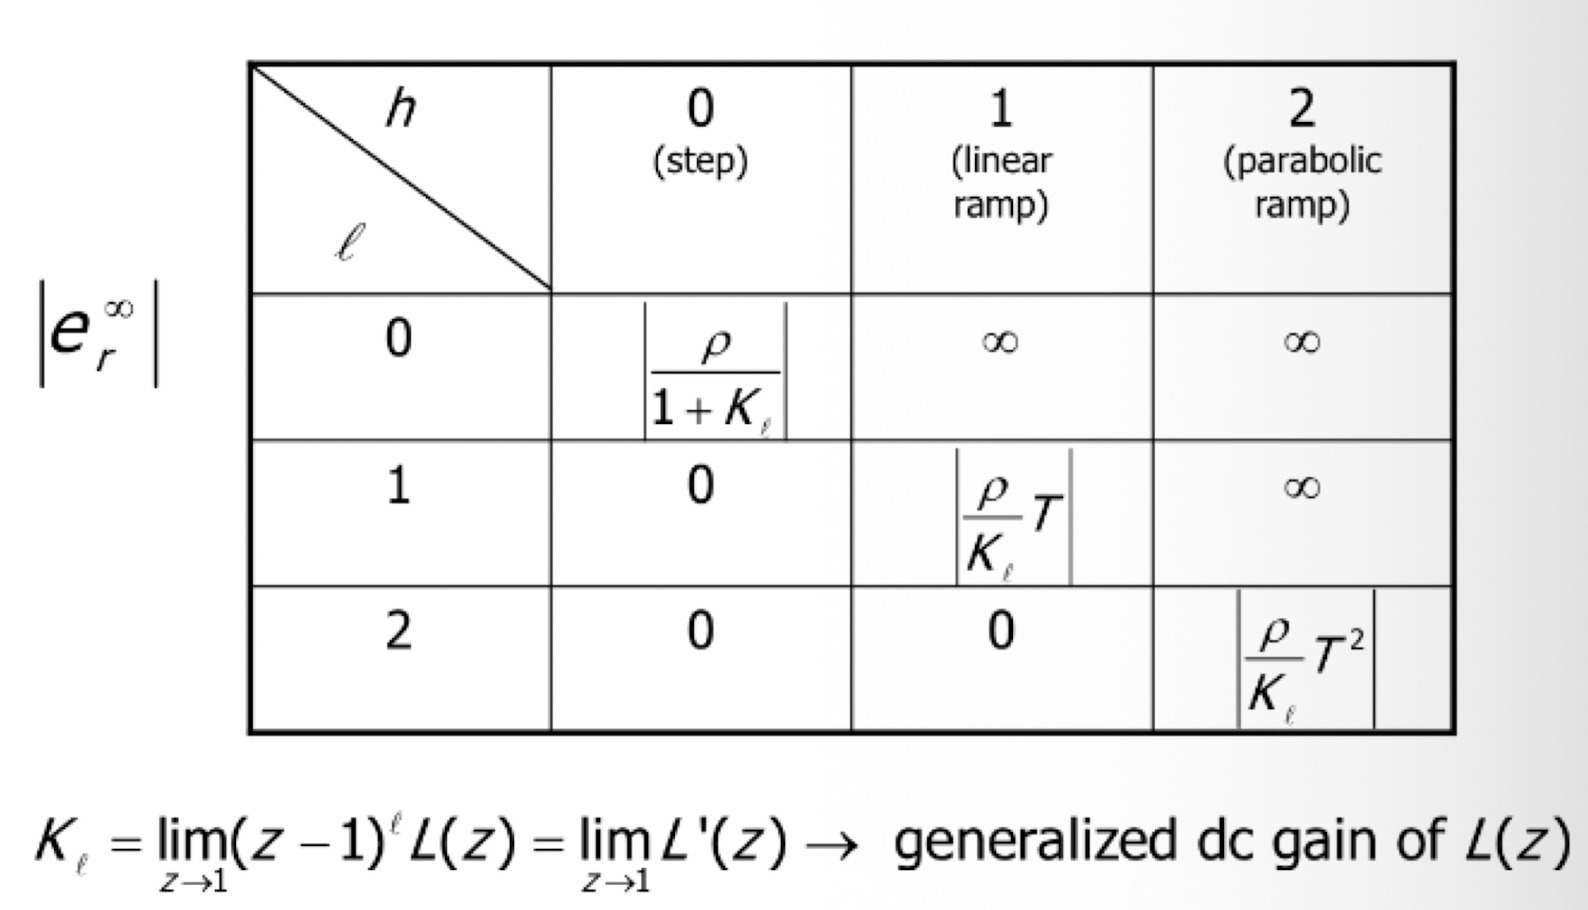

So we need l = 1 => since l2 = 0 => l1 = 1 **AND** a condition on K_l (gerenalized dc gain of L(z))

In particular, we get that 

K_l >= rho*T/e_inf = 2        (since rho is the slope and it's = 1 and T the sampling time)

So we get:

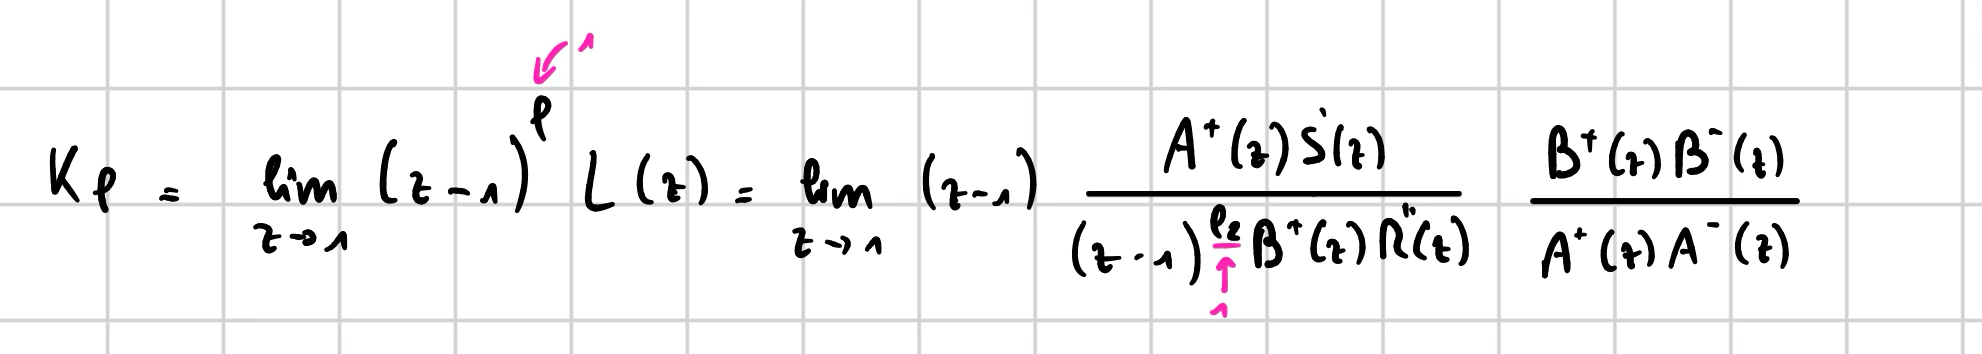

We'll analyse it later on. Now let's focus on constructing dioph eq

l1 = 0; % power of (z-1) term in G
l2 = 1; % power of (z-1) term in C
l = l1+l2;

Kl = 2;
n_add = 1; % IMPORTANT!!!! is the extra condition that I have 

deg_A = 2; % G has 2 poles
deg_A1 = 2; % no roots in 1 in G
deg_Aplus = 1;
deg_Aminus = 1;
deg_Bplus = 0;
deg_Bminus = 1;

% by def
deg_S1 = l + deg_Aminus - 1 + n_add

deg_S1 = 2

deg_R2 = deg_A1 - deg_Bplus + l1 - 1 + n_add

deg_R2 = 2

deg_Am = l + deg_Aminus + deg_A1 - deg_Bplus + l1 - 1 + n_add 

deg_Am = 4

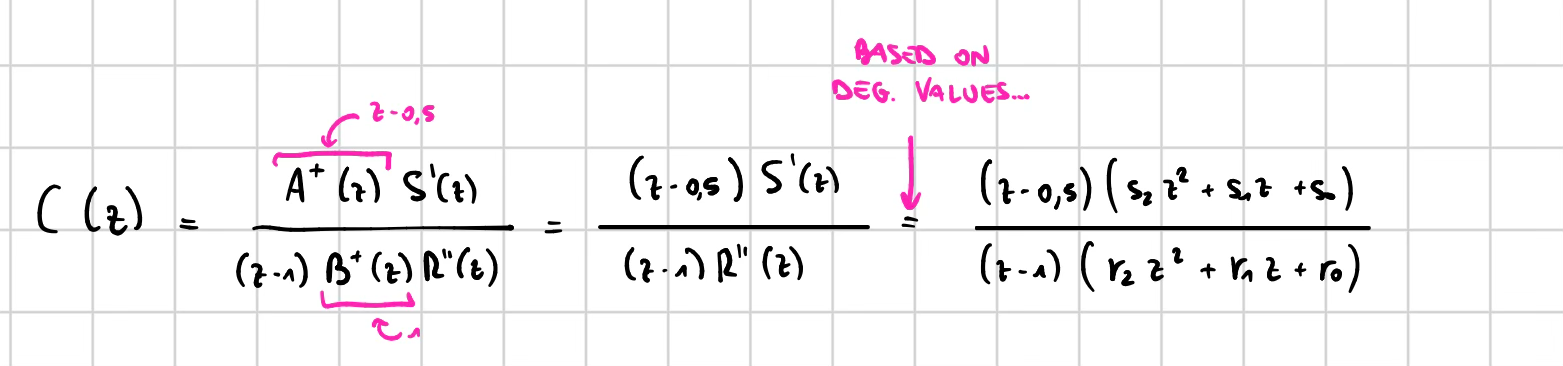

For Am, I can choose the exact same poles of example 1 (since deg Am = 4)

r = [0.2+0.2*1i, 0.2-0.2*1i, 0.1-0.1*1i, 0.1+0.1*1i]; % roots vector
Am = poly(r)'; % Am coeff

Now I have to solve diophantine equation. At this point I need to build the extra eq that is needed for solving dioph eq

extra_eq = [Kl*polyval(A_minus,1)*ones(1,3) -polyval(B_minus,1)*ones(1,3)];
% NOTE: i use polyval
% This MATLAB function evaluates the polynomial p at each point in x.
% Syntax
%       y = polyval(p,x)

Now I can finally solve diophantine equation

% before I define Adioph and Bdioph
A_dioph = conv([1 -1], A_minus);
B_dioph = B_minus;

[R2, S1] = diop_solver(A_dioph,B_dioph,Am,deg_R2, n_add, extra_eq);
% NB Adioph Bdioph & Am can be both row or column

Then, I can build the controller

R = conv([1 -1], R2); % I can omit B+ term since B+ = 1
S = conv(A_plus,S1);
C = zpk(tf(S(:)',R(:)', 1));
% NB in tf S and R must be row

And, at the end, check if poles of closed loop tf are exacly the chosen ones

W = minreal(zpk(feedback(C*G,1)), 1e-2);
p_W = pole(W)

p_W =    0.2000 + 0.2000i
   0.2000 - 0.2000i
   0.1000 + 0.1000i
   0.1000 - 0.1000i
